# Transducer Design

Transducer 1

% Define common properties
transducer_info = struct();
transducer_info.Frequency = 4e4;    % 40kHz (operating frequency of transducer)
transducer_info.Pressure = 1;       % How to set this parameter?
transducer_info.Type = 'circle';
transducer_info.Radius = 5e-3;      
transducer_info.rotate = [0, 0, 0];
transducer_info.medium = 'air';

% Positions and phases for the transducers (1 row)
positions = [];
for k = 1:4
    positions(k) = 0.005 + 0.01 * (k-1);
end

% PFC_PhaseCalculate_for16(target[x,y], array, focal point z(m))
phases = PFC_PhaseCalculate_for16([0.005, 0.005], [4,4], 0.15)

phases =     1.5708    0.7854         0    2.3562
    0.7854    0.7854         0    1.5708
         0         0    2.3562    1.5708
    2.3562    1.5708    1.5708         0


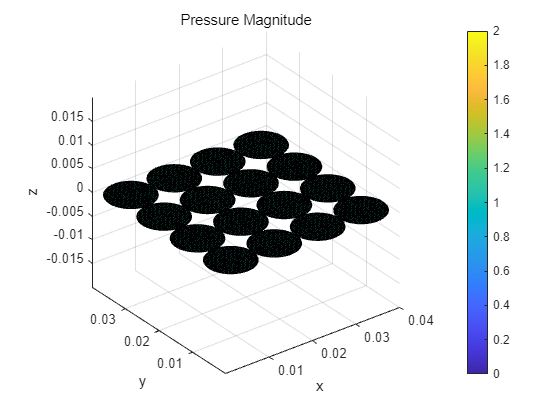

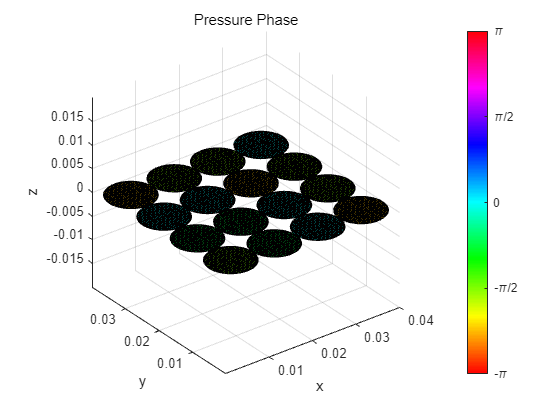

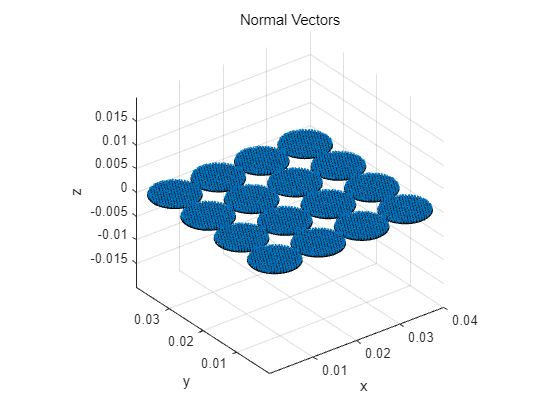


% Counter for linear indexing into transducer_object
index = 1;

% Populate the transducer objects
for i = 1:4
    for j = 1:4
        % Update position and phase
        transducer_info.position = [positions(j), positions(i), 0];
        % transducer_info.Phase = phases(i,j);
        transducer_info.Phase = phases(i,j);
        transducer_object(index) = PFC_Make3DTransducer(transducer_info);

        % Increment index for next transducer
        index = index + 1;
    end
end

% transducer_info.position = [0.005, 0.005, 0];
% transducer_info.Phase = 0;
% transducer_object(1) = PFC_Make3DTransducer(transducer_info);
% 
% transducer_info.position = [0.015, 0.005, 0];
% transducer_info.Phase = (pi*0.375);
% transducer_object(2) = PFC_Make3DTransducer(transducer_info);
% 
% transducer_info.position = [0.025, 0.005, 0];
% transducer_info.Phase = (pi*0.625);
% transducer_object(3) = PFC_Make3DTransducer(transducer_info);
% 
% transducer_info.position = [0.035, 0.005, 0];
% transducer_info.Phase = (pi*0.75);
% transducer_object(4) = PFC_Make3DTransducer(transducer_info);
% %%
% transducer_info.position = [0.005, 0.015, 0];
% transducer_info.Phase = (pi*0.375);
% transducer_object(5) = PFC_Make3DTransducer(transducer_info);
% 
% transducer_info.position = [0.015, 0.015, 0];
% transducer_info.Phase = (pi*0.625);
% transducer_object(6) = PFC_Make3DTransducer(transducer_info);
% 
% transducer_info.position = [0.025, 0.015, 0];
% transducer_info.Phase = (pi*0.875);
% transducer_object(7) = PFC_Make3DTransducer(transducer_info);
% 
% transducer_info.position = [0.035, 0.015, 0];
% transducer_info.Phase = (pi*1.125);
% transducer_object(8) = PFC_Make3DTransducer(transducer_info);
% %%
% transducer_info.position = [0.005, 0.025, 0];
% transducer_info.Phase = (pi*0.625);
% transducer_object(9) = PFC_Make3DTransducer(transducer_info);
% 
% transducer_info.position = [0.015, 0.025, 0];
% transducer_info.Phase = (pi*0.875);
% transducer_object(10) = PFC_Make3DTransducer(transducer_info);
% 
% transducer_info.position = [0.025, 0.025, 0];
% transducer_info.Phase = (pi*1.25);
% transducer_object(11) = PFC_Make3DTransducer(transducer_info);
% 
% transducer_info.position = [0.035, 0.025, 0];
% transducer_info.Phase = (pi*1.375);
% transducer_object(12) = PFC_Make3DTransducer(transducer_info);
% %%
% transducer_info.position = [0.005, 0.035, 0];
% transducer_info.Phase = (pi*0.75);
% transducer_object(13) = PFC_Make3DTransducer(transducer_info);
% 
% transducer_info.position = [0.015, 0.035, 0];
% transducer_info.Phase = (pi*1.125);
% transducer_object(14) = PFC_Make3DTransducer(transducer_info);
% 
% transducer_info.position = [0.025, 0.035, 0];
% transducer_info.Phase = (pi*1.375);
% transducer_object(15) = PFC_Make3DTransducer(transducer_info);
% 
% transducer_info.position = [0.035, 0.035, 0];
% transducer_info.Phase = (pi*1.5);
% transducer_object(16) = PFC_Make3DTransducer(transducer_info);


% Draw all transducers in 3D once
PFC_DrawTransducer3D(transducer_object, '-');

## Frequency Domain

input_source.Type = 'frequency';
input_source.reading_list = 1e6; % [Hz]

## Simulation Space

reading_pos_x = 0 : 0.25e-3 : 40e-3;          % Simulation Area
reading_pos_y = 0 : 0.25e-3 : 40e-3;          % Simulation Area
reading_pos_z = 100e-3 : 0.25e-3 : 200e-3;          % Simulation Area

## Run Frequency Domain Simulation

% xz plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, 0.005, reading_pos_z);

Started at 2024-06-17 12:29:24
Finished at 2024-06-17 12:29:58
Progressed time : 00:00:34


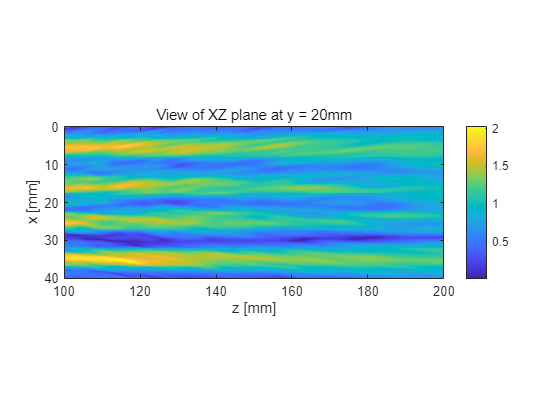


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_z.*1e3, reading_pos_x.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XZ plane at y = 20mm');
colorbar;
xlabel('z [mm]');
ylabel('x [mm]');



% xy plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, reading_pos_y, 0.1);

Started at 2024-06-17 12:29:59
Finished at 2024-06-17 12:30:13
Progressed time : 00:00:14


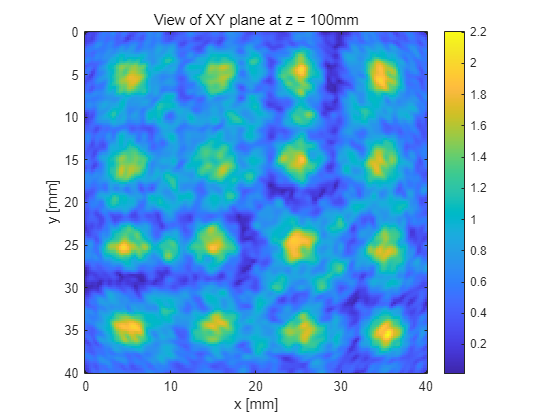


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XY plane at z = 100mm');
colorbar;
xlabel('x [mm]');
ylabel('y [mm]');